# Ajuste de Sistemas de Inferencia Difusos

## Introducción

El ajuste u optimización de sistemas de inferencia se encarga de encontrar un conjunto de parámetros que produzcan el resultado más óptimo. Esto se logra utilizando una *función de costo* que compara la salida que nos da nuestro FIS con parámetros actuales y la compara con un resultado que sabemos que es el correcto. Los algoritmos de optimización se encargan de minimizar la función de costo modificando los parámetros de nuestro FIS. Esta función de costo cambia dependiendo de los resultados que estemos esperando.

En un FIS podríamos modificar una gran cantidad de parámetros para encontrar cuál es el mejor sistema para nuestra aplicación, por ejemplo, podemos cambiar el número de funciones de membresía de una entrada y de salida, qué tipo de funciones son, además de los parámetros de la propia función de membresía, también podemos cambiar la cantidad de reglas de inferencia y las sentencias que las componen. Optimizar todos estos parámetros es muy complicado ya que el número de combinaciones posibles de todos los parámetros va creciendo exponencialmente.

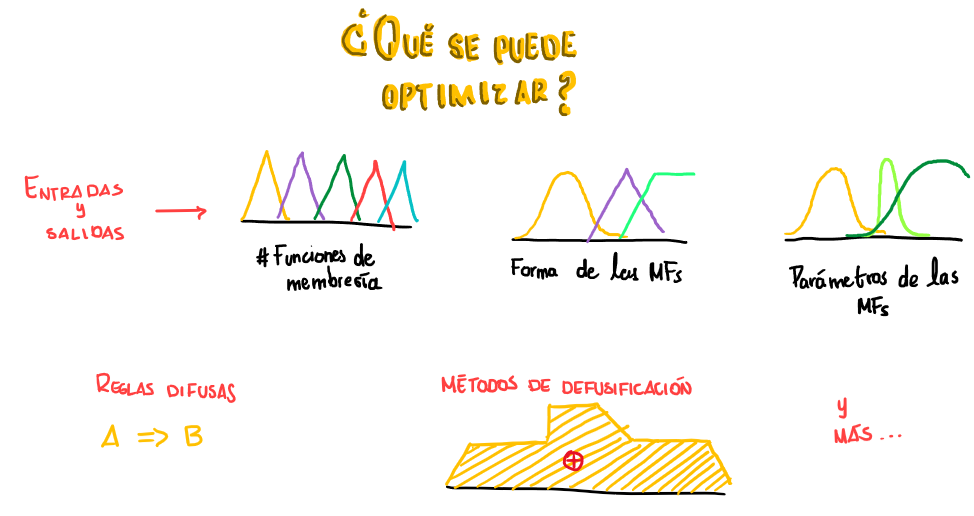

Para evitar tener que optimizar todos los parámetros a la vez, lo que se hace es que, utilizando nuestra experiencia e intuición, asignar valores fijos a algunos de estos parámetros, de forma que sólo tengamos que optimizar un pequeño conjunto de ellos. Generalmente se optimizan las reglas difusas y los parámetros de las funciones de membresía.

Al diseñar sistemas de inferencia muy complejos tenemos que lidiar con una gran cantidad de entradas y de parámetros de funciones de membresía. Estos se peuden optimizar con diferentes algoritmos que generan parámetros iniciales y luego se evalúa con los datos de entrada. Si tenemos un conjunto de datos de entrada/salida entonces se actualizan los parámetros comparando la salida actual del FIS con la salida esperada de nuestro conjunto.

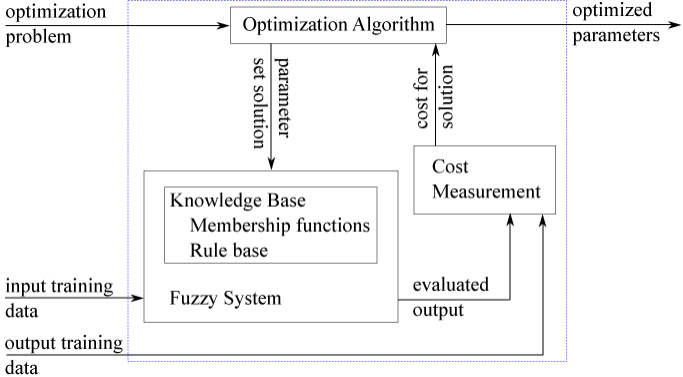

Algunos métodos de optimización son:

- Algoritmos genéticos.

- Optimización por enjambre de partículas.

- Búsqueda de patrones.

- Recocido simulado.

- Sistemas Adaptativos de Inferencia Neuro-Difusa (ANFIS).

## Optimización de los parámetros de funciones de membresía

En este ejemplo veremos cómo optimizar los parámetros de funciones de membresía utilizando algunas funciones y objetos incluídos en la Fuzzy Logic Toolbox de Matlab.

% Creamos un FIS tipo Mamdani
fis = mamfis;
fis = addInput(fis, [0 10], 'NumMFs', 3);
fis = addOutput(fis, [0 1], 'NumMFs', 3);
fis = addRule(fis, [1 1 1 1; 1 1 1 1; 1 1 1 1]);
fis.Rules

ans =   1×3 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf1 => output1=mf1 (1)"
    2    "input1==mf1 => output1=mf1 (1)"
    3    "input1==mf1 => output1=mf1 (1)"


% Parametros que podemos optimizar de las entradas y la salida.
% En este caso podemos optimizar 3 funciones de membresía para la entrada
% y 3 para la salida.
[in, out] = getTunableSettings(fis)

in =   VariableSettings with properties:

                   Type: "input"
           VariableName: "input1"
    MembershipFunctions: [1×3 fuzzy.tuning.MembershipFunctionSettings]
                FISName: "fis"


out =   VariableSettings with properties:

                   Type: "output"
           VariableName: "output1"
    MembershipFunctions: [1×3 fuzzy.tuning.MembershipFunctionSettings]
                FISName: "fis"


in.MembershipFunctions(1).Parameters

ans =   NumericParameters with properties:

    Minimum: [-Inf -Inf -Inf]
    Maximum: [Inf Inf Inf]
       Free: [1 1 1]


Para cada parámetro de una función de membresía podemos especificar si se debería optimizar y sus valores mínimos y máximos. Como podemos observar, por defecto todos están disponibles para optimización y los rangos se inicializan como `[-Inf, Inf]`.

Podemos hacer que alguna función de membresía no pueda modificarse utilizando la función `setTunable. `Por ejemplo, si queremos que la función de membresía de `input1 `no pueda se modificada, hacemos lo siguiente:

in(1).MembershipFunctions(1) = setTunable(in(1).MembershipFunctions(1), false)

in =   VariableSettings with properties:

                   Type: "input"
           VariableName: "input1"
    MembershipFunctions: [1×3 fuzzy.tuning.MembershipFunctionSettings]
                FISName: "fis"


También podemos hacer que un parámetro en específico pueda o no ser optimizable. Por ejemplo, si queremos que el primer parámetro de la función de membresía 2 de `input1 `no pueda modificarse hacemos lo siguiente:

in(1).MembershipFunctions(2).Parameters.Free(1) = false;
% En el atributo Free aparece un 0 en el primer elemento del vector, lo que
% indica que no puede optimizarse el primer parametro.
in(1).MembershipFunctions(2).Parameters

ans =   NumericParameters with properties:

    Minimum: [-Inf -Inf -Inf]
    Maximum: [Inf Inf Inf]
       Free: [0 1 1]


Podemos modificar los rangos de los parámetros de las funciones de membresía. Por ejemplo, hacemos que los parámetros 2 y 3 de la tercera función de membresía de `input1` tengan un valor mínimo de 0.

in(1).MembershipFunctions(3).Parameters.Minimum(2:3) = 0;
in(1).MembershipFunctions(3).Parameters

ans =   NumericParameters with properties:

    Minimum: [-Inf 0 0]
    Maximum: [Inf Inf Inf]
       Free: [1 1 1]


Igualmente podemos modificar los valores máximos, por ejemplo, hacemos que los parámetros 2 y 3 de la tercera función de membresía de `input1` sean 15.

in(1).MembershipFunctions(3).Parameters.Maximum(2:3) = 15;
in(1).MembershipFunctions(3).Parameters

ans =   NumericParameters with properties:

    Minimum: [-Inf 0 0]
    Maximum: [Inf 15 15]
       Free: [1 1 1]


Finalmente, podemos hacer que las funciones de membresía de la salida no puedan ser optimizadas.

out = setTunable(out, false);

Ahora utilizaremos como datos de entrenamiento la función


$$y=|\frac{\sin \left(2x\right)}{e^{\frac{x}{5}} }|$$


Lo que buscamos es que para un rango de valores de $x$ nuestro FIS pueda darnos como salida los valores de la función anterior.

x = (0:0.1:10)';
y = abs(sin(2 * x) ./ exp(x / 5));

Para optimizar los parámetros de las funciones de membresía utilizamos `tunefis`. Primero hay que preparar las opciones de optimización como el método y opciones propias del método de ajuste. En este caso se utilizará un algoritmo genético de hasta 5 generaciones. (Para poder tener acceso al método de algoritmo genético se debe tener instalado `Global Optimization Toolbox`).

options = tunefisOptions("Method", "ga");
options.MethodOptions.MaxGenerations = 5; % 5 generaciones como maximo

Para comparar la salida actual de nuestro FIS con el valor de $y$ esperado utilizamos el valor absoluto de la diferencia entre las salidas, también llamada *norma 1*.

options.DistanceMetric = "norm1";

Ahora utilizamos `tunefis` para optimizar los parámetros de las funciones de membresía.

rng('default');
[fisout, optimout] = tunefis(fis, [in;out], x, y, options)


Single objective optimization:
5 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           32.84           32.84        0
    2              147           32.84           32.84        1
    3              194           32.84           32.84        2
    4              241           32.84           32.84        3
    5              288           32.84           32.84        4
Optimization terminated: maximum number of generations exceeded.


fisout =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×1 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


optimout = struct with fields:
    tuningOutputs: [1×1 struct]
    totalFcnCount: 288
     totalRuntime: 16.4867
     errorMessage: []


- `fisout` contiene los parámetros actualizados.

- `optimout` contiene salidas adicionales relacionadas con el método de optimización, así como mensajes de error.

Como en este caso modificamos `out` para que los parámetros de las funciones de membresía no puedan optimizarse, no es necesario incluirlo en los argumentos de `tunefis` y obtendremos el mismo resultado.

### Optimización de las reglas difusas

Además de optimizar los parámetros de las funciones de membresía, podemos optimizar las reglas difusas.

% Obtenemos las reglas difusas
[~, ~, rule] = getTunableSettings(fis)

rule =   3×1 RuleSettings array with properties:

    Index
    Antecedent
    Consequent
    FISName


Cada objeto `RuleSettings` contiene el nombre del FIS, el índice de la regla en el FIS y las sentencias de la regla (antecedente y consecuente). Para una sentencia de una regla se pueden modificar los siguientes parámetros:

- `AllowNot`: Permite el uso de la lógica con NOT. Por defecto esto está desactivado.

- `Free`: Permite que las sentancias de la regla puedan optimizarse (cambiando las funciones de membresía que participan en ella) Por defecto esto está activado.

- `AllowEmpty`: Habilita la ausencia de algunas variables de entrada/salida. Por defecto está activado.

rule(1).Antecedent

ans =   ClauseParameters with properties:

      AllowNot: 0
    AllowEmpty: 1
          Free: 1


% Activamos la lógica NOT
rule(1).Antecedent.AllowNot = true;
% Hacemos que el consecuente de la regla 1 no pueda optimizarse
rule(1).Consequent.Free = 0;
% No permitimos la ausencia de variables en el consecuente de la regla 2
rule(2).Consequent.AllowEmpty = false;
% No permitimos que la regla 3 pueda optimizarse
rule(3) = setTunable(rule(3), false);
% En opciones cambiamos a distancia a la norma 2 (distancia euclidea)
options.DistanceMetric = "norm2";
% Optimizamos las reglas
rng("default");
fisout = tunefis(fis, rule, x, y, options)


Single objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           1.648           2.575        0
    2              147           1.648           2.448        1
    3              194           1.648           2.212        2
    4              241           1.648           2.052        3
    5              288           1.648           1.874        4
Optimization terminated: maximum number of generations exceeded.


fisout =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×2 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


fisout.Rules

ans =   1×2 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1~=mf2 => output1=mf1 (1)"
    2    "input1==mf1 => output1=mf3 (1)"


### Aprendizaje

Podemos indicar que se agreguen nuevas reglas de inferencia para nuestro FIS utilizando la opción `learning` de la propiedad `OptimizationType` de nuestro objeto `tunefisOptions` (la variable `options`). Por defecto, el valor de esta propiedad es `tuning`, que se encarga de optimizar las reglas y parámetros que se encuentren definidas.

fisin = fis;
% Dejamos a fisin con 0 reglas
fisin.Rules = [];
options.OptimizationType = "learning";

% Indicamos el número máximo de reglas. Si no se especifica, el numero
% maximo de reglas esta determinado por el numero de combinaciones de las
% entradas
options.NumMaxRules = 3;
% Cambiamos la metrica a RMSE
options.DistanceMetric = "rmse";
rng('default');
fisout = tunefis(fisin, [], x, y, options)


Single objective optimization:
6 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           0.165          0.2956        0
    2              590           0.165          0.2805        1
    3              780           0.165          0.2578        2
    4              970           0.165          0.2393        3
    5             1160           0.165          0.2322        4
Optimization terminated: maximum number of generations exceeded.


fisout =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×3 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


fisout.Rules

ans =   1×3 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf3 => output1=mf1 (1)"
    2    "input1==mf1 => output1=mf2 (1)"
    3    "input1==mf2 => output1=mf1 (1)"


Como podemos observar, se agregaron 3 reglas difusas nuevas. Podríamos eliminar algunas de ellas y repetir el proceso, lo único que hay que hacer es asignarles un valor vacío a las reglas que queremos quitar y posteriormente volver a utilizar `tunefis`.

% Eliminamos las ultimas dos reglas difusas
fisout.Rules(2:end) = [];
rng('default');
fisout = tunefis(fisin, [], x, y, options);


Single objective optimization:
6 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           0.165          0.2956        0
    2              590           0.165          0.2805        1
    3              780           0.165          0.2578        2
    4              970           0.165          0.2393        3
    5             1160           0.165          0.2322        4
Optimization terminated: maximum number of generations exceeded.


fisout.Rules

ans =   1×3 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf3 => output1=mf1 (1)"
    2    "input1==mf1 => output1=mf2 (1)"
    3    "input1==mf2 => output1=mf1 (1)"


También podemos optimizar los parámetros de nuestras reglas que ya se encuentren y agregar nuevas, pasando el argumento de `rule` a `tunefis`.

% Eliminamos las ultimas dos reglas difusas
fisout.Rules(2:end) = [];
fisout.Rules(1).Antecedent = 1;
fisout.Rules(1).Consequent = 1;
[~, ~, rule] = getTunableSettings(fisout);
rng('default');
fisout = tunefis(fisin, rule, x, y, options);


Single objective optimization:
8 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           0.165          0.3063        0
    2              590           0.165          0.2845        1
    3              780           0.165          0.2549        2
    4              970           0.165          0.2344        3
    5             1160           0.165          0.2153        4
Optimization terminated: maximum number of generations exceeded.


fisout.Rules

ans =   1×3 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf1 => output1=mf2 (1)"
    2    "input1==mf2 => output1=mf1 (1)"
    3    "input1==mf3 => output1=mf1 (1)"


### Optimizar funciones de membresía y reglas

Podemos optimizar los parámetros de las funciones de membresía y las reglas difusas de forma simultánea, pasando como argumento los tres valores a `tunefis`.

[in, out, rule] = getTunableSettings(fis);
options = tunefisOptions('Method', 'ga');
options.MethodOptions.MaxGenerations = 5;
rng('default');
fisout = tunefis(fis, [in; out; rule], x, y, options);


Single objective optimization:
24 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400           0.165           0.296        0
    2              590          0.1638          0.2821        0
    3              780          0.1625          0.2697        0
    4              970          0.1625          0.2616        1
    5             1160          0.1604          0.2512        0
Optimization terminated: maximum number of generations exceeded.


Para mejorar el tiempo de optimización se pueden seguir los siguientes pasos:

- Optimizar o aprender las reglas.

- Optimizar las funciones de membresía y las reglas.

### Generar un FIS

Podemos utilizar la función `genfis` para crear un FIS con reglas iniciales la cual podemos optimizar después.

goptions = genfisOptions( 'GridPartition' , 'NumMembershipFunctions' ,5, ...
 'InputMembershipFunctionType' , 'gaussmf' , ...
 'OutputMembershipFunctionType' , 'constant' );

% Inicializamos un FIS
fisin = genfis(x, y, goptions);
[in, out, rule] = getTunableSettings(fisin);

% Optimizamos
toptions = tunefisOptions('Method', 'patternsearch');
toptions.MethodOptions.MaxIterations= 25;
rng('default');
fisout = tunefis(fisin, [in; out], x, y, toptions);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.346649             1      
    1          19       0.346649           0.5     Refine Mesh
    2          37       0.273812             1     Successful Poll
    3          38       0.236413             2     Successful Poll
    4          39       0.190794             4     Successful Poll
    5          40       0.182142             8     Successful Poll
    6          47       0.182142             4     Refine Mesh
    7          49       0.162927             8     Successful Poll
    8          56       0.162927             4     Refine Mesh
    9          67       0.162927             2     Refine Mesh
   10          69       0.159539             4     Successful Poll
   11          80       0.159539             2     Refine Mesh
   12          92       0.159539             1     Refine Mesh
   13          94       0.159421             2     Successful Poll
   14         106       0.159373          

## Optimización de árboles difusos

Para optimizar los FIS de un árbol difuso se realizan dos pasos.

- Optimización y aprendizaje de los FIS en el árbol.

- Aprendizaje de los parámetros de las funciones de membresía en el árbol.

Tomemos como ejemplo un FIS que aproxime la función $\frac{\sin \left(x\right)+\cos \left(x\right)}{\exp \left(x\right)}$ cuyo diagrama se muestra a continuación:

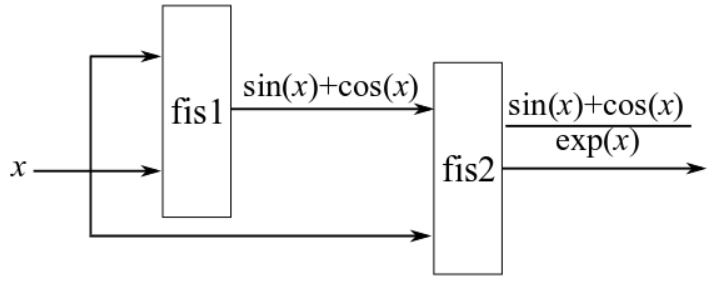

Para esto utilizaremos un sistema de inferencia tipo Sugeno, ya que el método de defusificación es más rápido que el de Mamdani. Añadimos dos entradas con un rango de $[0,10]$ y con 3 funciones de membresía de tipo gaussianas, este FIS aproximará a $\sin \left(x\right)+\cos \left(x\right)$.

fis1 = sugfis('Name', 'fis1');
fis1 = addInput(fis1, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');
fis1 = addInput(fis1, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');

Agregamos una salida con 9 funciones de membresía correspondientes a las 9 combinaciones de las entradas.

fis1 = addOutput(fis1, [-1.5 1.5], 'NumMFs', 9);

Ahora pasamos a `fis2`, que será igual un FIS tipo Sugeno con dos entradas, una con rango $[-1.5,1.5]$ que corresponde a la salida del FIS anterior y otra con los mismos parámetros que las entradas de `fis1`.

fis2 = sugfis('Name', 'fis2');
fis2 = addInput(fis2, [-1.5 1.5], 'NumMFs', 3, 'MFType', 'gaussmf');
fis2 = addInput(fis2, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');

% Añadimos una salida con rango de [0,1]
fis2 = addOutput(fis2, [0 1], 'NumMFs', 9);

Ya tenemos nuestros FIS que forman el árbol difuso, ahora hay que conectarlos, para ello es necesario crear Strings que contengan los pares de nodos que forman las conexiones. Por ejemplo, en nuestro árbol la salida de `fis1` se conecta con la entrada 1 de `fis2`, entonces debemos crear un vector de strings con ambos nodos de la forma `["fis1/output" "fis2/input1"]`.

con1 = ["fis1/output1" "fis2/input1"];
con2 = ["fis1/input1" "fis1/input2"];
con3 = ["fis1/input2" "fis2/input2"];

% Creamos un arbol difuso
fisT = fistree([fis1 fis2], [con1; con2; con3]);
% Añadimos una salida adicional al arbol para obtener la salida de fis1
fisT.Outputs = ["fis1/output1"; fisT.Outputs];

% Datos de entrenamiento
x = (0:0.1:10)';
y1 = sin(x) + cos(x);
y2 = y1 ./ exp(x);
y = [y1 y2];

% Primero utilizamos aprendizaje para las reglas de nuestro arbol
options = tunefisOptions('Method', 'particleswarm', 'OptimizationType', 'learning');
options.MethodOptions.MaxIterations = 5;
rng('default');
fisTout1 = tunefis(fisT, [], x, y, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100          0.6682          0.9395        0
    1             200          0.6682           1.023        0
    2             300          0.6652          0.9308        0
    3             400          0.6259           0.958        0
    4             500          0.6259           0.918        1
    5             600          0.5969          0.9179        0
Optimization ended: number of iterations exceeded OPTIONS.MaxIterations.


% Optimizamos las funciones de nuestros FIS junto a las reglas
options.Method = 'patternsearch';
options.MethodOptions.MaxIterations = 25;
[in, out, rule] = getTunableSettings(fisTout1);
rng('default');
fisTout2 = tunefis(fisTout1, [in; out; rule], x, y, options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.596926             1      
    1           3       0.551284             2     Successful Poll
    2          13       0.548551             4     Successful Poll
    3          20       0.546331             8     Successful Poll
    4          33       0.527482            16     Successful Poll
    5          33       0.527482             8     Refine Mesh
    6          61       0.511532            16     Successful Poll
    7          61       0.511532             8     Refine Mesh
    8          92       0.505355            16     Successful Poll
    9          92       0.505355             8     Refine Mesh
   10         128       0.505355             4     Refine Mesh
   11         175       0.487734             8     Successful Poll
   12         212       0.487734             4     Refine Mesh
   13         265       0.487734             2     Refine Mesh
   14         275       0.486926          

También podemos optimizar cada FIS por separado y luego podemos optimizar ambos al mismo tiempo para evitar que nuestro modelo se ajuste demasiado a los datos de entrenamiento. Para obtener los parámetros de un FIS usamos la función `getTunableSettings` indicando el nombre del FIS.

% Optimizamos fis1
[in, out, rule] = getTunableSettings(fisTout1, "FIS", "fis1");
rng('default');
fisTout2 = tunefis(fisTout1, [in; out; rule], x, y, options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.596926             1      
    1           3       0.551284             2     Successful Poll
    2          18       0.510362             4     Successful Poll
    3          28       0.494804             8     Successful Poll
    4          56       0.494804             4     Refine Mesh
    5          84       0.493422             8     Successful Poll
    6         107       0.492883            16     Successful Poll
    7         107       0.492883             8     Refine Mesh
    8         136       0.492883             4     Refine Mesh
    9         171       0.492883             2     Refine Mesh
   10         178       0.491534             4     Successful Poll
   11         213       0.491534             2     Refine Mesh
   12         229       0.482682             4     Successful Poll
   13         264       0.482682             2     Refine Mesh
   14         279       0.446645          

% Optimizamos fis2
[in, out, rule] = getTunableSettings(fisTout2, "FIS", "fis2");
rng('default');
fisTout3 = tunefis(fisTout2, [in; out; rule], x, y, options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.390338             1      
    1           2       0.374103             2     Successful Poll
    2           5       0.373855             4     Successful Poll
    3          10       0.356619             8     Successful Poll
    4          33       0.356619             4     Refine Mesh
    5          43       0.350715             8     Successful Poll
    6          65       0.349417            16     Successful Poll
    7          65       0.349417             8     Refine Mesh
    8          87       0.349417             4     Refine Mesh
    9          91       0.349356             8     Successful Poll
   10         112       0.349356             4     Refine Mesh
   11         138       0.346102             8     Successful Poll
   12         159       0.346102             4     Refine Mesh
   13         172       0.345938             8     Successful Poll
   14         193       0.345938      


% Optimizamos fis1 y fis2 al mismo tiempo
[in, out, rule] = getTunableSettings(fisTout3);
rng('default');
fisTout4 = tunefis(fisTout3, [in; out; rule], x, y, options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.333193             1      
    1           8       0.326804             2     Successful Poll
    2          91       0.326432             4     Successful Poll
    3         116       0.326261             8     Successful Poll
    4         154       0.326261             4     Refine Mesh
    5         205       0.326261             2     Refine Mesh
    6         302       0.326092             4     Successful Poll
    7         352       0.326092             2     Refine Mesh
    8         391       0.325964             4     Successful Poll
    9         441       0.325964             2     Refine Mesh
   10         478        0.32578             4     Successful Poll
   11         528        0.32578             2     Refine Mesh
   12         562       0.325691             4     Successful Poll
   13         612       0.325691             2     Refine Mesh
   14         713       0.229273          

Finalmente podemos observar la aproximación que realiza nuestro FIS.

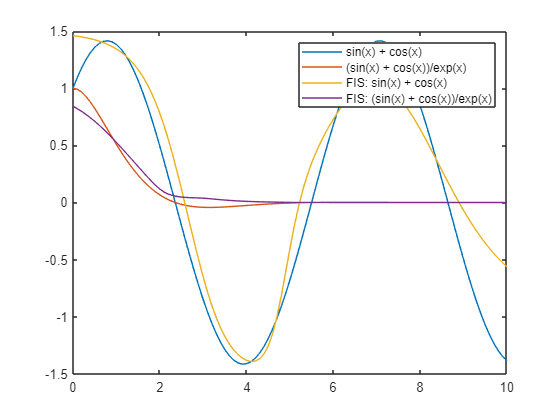

output = evalfis(fisTout4, x);
figure;
plot(x,y);
hold on;
plot(x, output);
legend('sin(x) + cos(x)', '(sin(x) + cos(x))/exp(x)', 'FIS: sin(x) + cos(x)', ...
       'FIS: (sin(x) + cos(x))/exp(x)');

### Personalizar el proceso de optimización

Podemos especificar una función de costo personalizada (anteriormente utilizamos funciones como `rmse` o `norm1`) o podemos especificar un método de optimización personalizado.

#### Función de costo personalizada

Usar una función de costo personalizada tiene ventajas como usar un modelo personalizado sin tener que usar datos de entrenamiento o poder combinar las salidas de los componentes de diferentes FIS o de un árbol difuso usando operaciones matemáticas. 

En el siguiente ejemplo, retomamos el caso de la función anterior $\frac{\sin \left(x\right)+\cos \left(x\right)}{\exp \left(x\right)}$. En este caso podríamos aproximar cada función una por una y posteriormente combinarlas todas como en el siguiente diagrama:

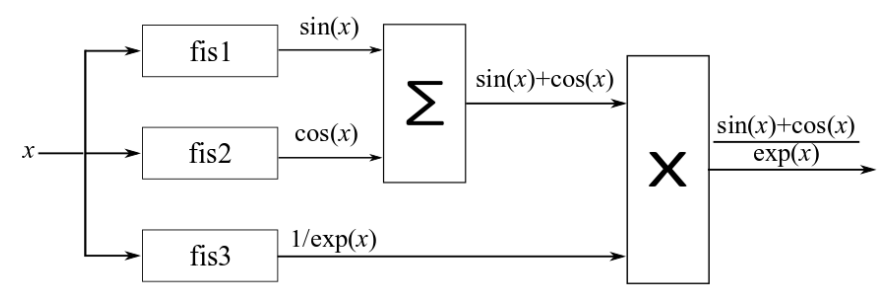

fis1 = sugfis('Name', 'fis1');
fis1 = addInput(fis1, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');
fis1 = addOutput(fis1, [-1 1], 'NumMFs', 3);

fis2 = sugfis('Name', 'fis2');
fis2 = addInput(fis2, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');
fis2 = addOutput(fis2, [-1 1], 'NumMFs', 3);

fis3 = sugfis('Name', 'fis3');
fis3 = addInput(fis3, [0 10], 'NumMFs', 3, 'MFType', 'gaussmf');
fis3 = addOutput(fis3, [0 1], 'NumMFs', 3);

% Conexiones para el arbol difuso, notemos que unicamente establecemos las
% conexiones de las entradas
con = ["fis1/input1" "fis2/input1"; "fis2/input1" "fis3/input1"];
fisT = fistree([fis1 fis2 fis3], con);

% Datos de entrenamiento
x = (0:0.1:10)';
y1 = sin(x) + cos(x);
y2 = y1 ./ exp(x);
y = [y1; y2];

Para agregar las operaciones de suma y multiplicación debemos utilizar una función de costo personalizada. En este caso se utiliza la función `customcostfcn`. Nuestro árbol difuso se encargará de evaluar las tres funciones y luego nuestra función de costo personalizada realizará la suma y la multiplicación para poder evaluar a nuestro FIS.

% Obtenemos las reglas difusas por aprendizaje
options = tunefisOptions('Method', 'particleswarm', 'OptimizationType', "learning");
options.MethodOptions.MaxIterations = 5;
rng('default');
fisTout1 = tunefis(fisT, [], @(fis)customcostfcn(fis, x, y), options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           0.746            1.31        0
    1             200          0.5089           1.249        0
    2             300          0.5089           1.086        1
    3             400          0.5089           1.112        2
    4             500          0.5089           1.106        3
    5             600          0.4999           1.051        0
Optimization ended: number of iterations exceeded OPTIONS.MaxIterations.


% Optimizamos todos los parametros
options.Method = 'patternsearch';
options.MethodOptions.MaxIterations = 25;
[in, out, rule] = getTunableSettings(fisTout1);
fisTout2 = tunefis(fisTout1, [in;out;rule], @(fis)customcostfcn(fis, x, y), options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.499882             1      
    1          13       0.499864             2     Successful Poll
    2          51       0.499727             4     Successful Poll
    3          72       0.499727             2     Refine Mesh
    4         117       0.499727             1     Refine Mesh
    5         157       0.499542             2     Successful Poll
    6         170       0.499485             4     Successful Poll
    7         191       0.499485             2     Refine Mesh
    8         217       0.499483             4     Successful Poll
    9         238       0.499483             2     Refine Mesh
   10         275       0.499483             4     Successful Poll
   11         296       0.499483             2     Refine Mesh
   12         340       0.499483             1     Refine Mesh
   13         381       0.499483             2     Successful Poll
   14         425       0.499483          

#### Método de optimización personalizado

Podemos usar un método personalizado de optimización de parámetros usando `getTunableSettings`, `getTunableValues` y `setTunableValues`. En este caso usaremos un FIS tipo Mamdani para aproximar la función $\sin \left(\theta \right)$ donde $\theta \in \left\lbrack 0,2\pi \right\rbrack$.

fisin = mamfis;
fisin = addInput(fisin, [0 2*pi], 'NumMFs', 5, 'MFType', 'gaussmf');
fisin = addOutput(fisin, [-1 1], 'NumMFs', 5, 'MFType', 'gaussmf');
% Añadimos 5 reglas
fisin = addRule(fisin, [1 1 1 1; 2 2 1 1; 3 3 1 1; 4 4 1 1]);
fisin.Rules

ans =   1×4 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf1 => output1=mf1 (1)"
    2    "input1==mf2 => output1=mf2 (1)"
    3    "input1==mf3 => output1=mf3 (1)"
    4    "input1==mf4 => output1=mf4 (1)"


% Para actualizaciones más rápidas
fisin.DisableStructuralChecks = true;
% Obtenemos las reglas
[~, ~, rule] = getTunableSettings(fisin);
% Deshabilitamos la optimizacion de los antecedentes, la logica not para
% los consecuentes y no permitimos que no haya alguna MF sin usar.
for i=1:numel(rule)
    rule(i).Antecedent.Free = false;
    rule(i).Consequent.AllowNot = false;
    rule(i).Consequent.AllowEmpty = false;
end

Usamos la función `customtunefis` para optimizar los parámetros de las reglas.

x = (0:0.1:2*pi)';
y = sin(x);

num_iter = 2;
ignoreinvp = false;
fisout = customtunefis(fisin, rule, x, y, num_iter, ignoreinvp);

Initial cost = 1.137215
Iteration 1: Cost = 0.273581
Iteration 2: Cost = 0.273581


fisout.Rules

ans =   1×4 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                   Description           
         ________________________________

    1    "input1==mf1 => output1=mf4 (1)"
    2    "input1==mf2 => output1=mf5 (1)"
    3    "input1==mf3 => output1=mf3 (1)"
    4    "input1==mf4 => output1=mf1 (1)"


## Optimización de un FIS tipo Mamdani

En este ejemplo utilizaremos un problema de regresión relacionado con la predicción del consumo de combustible (en millas por galón MPG) utilizando los siguientes datos de entrada de un automóvil:

- Número de cilindros.

- Desplazamiento.

- Caballos de fuerza.

- Peso.

- Aceleración.

- Año del modelo.

Matlab ya tiene datos referentes a este problema, los cuales podemos obtener utilizando `loadGasData.`

[data, name] = loadGasData;
% Removemos espacios en blanco
name = strtrim(string(name))

name = 1×7 string array
    "Cylinder"    "Disp"    "Power"    "Weight"    "Acceler"    "Year"    "MPG"


`data` contiene en cada columna los 7 atributos mostrados en `name`. La última columna son los datos de salida.

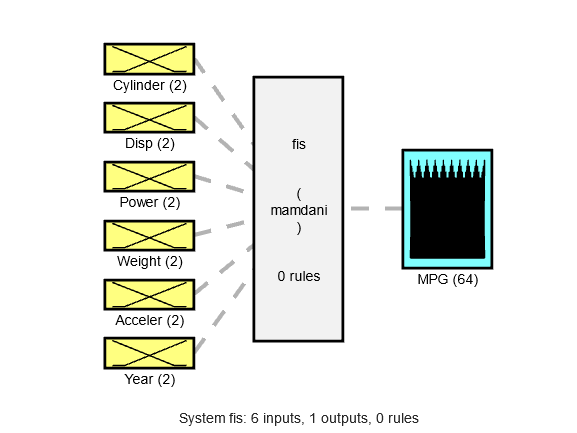

% Separamos los datos de entrada con los de salida
X = data(:, 1:6);
Y = data(:, 7);

% Dividimos los datos en entrenamiento y de validacion
trnX = X(1:2:end, :);
trnY = Y(1:2:end, :);
vldX = X(2:2:end, :);
vldY = Y(2:2:end, :);

% Obtenemos el rango de los datos para construir nuestro FIS
dataRange = [min(data)' max(data)'];

% Creamos un FIS tipo Mamdani
fisin = mamfis;
% Añadimos 6 entradas que son las 6 caracteristicas del auto
for i=1:6
    fisin = addInput(fisin, dataRange(i,:), 'Name', name(i), 'NumMFs', 2);
end
% Añadimos una salida con 64 MF, que son el numero de combinaciones de las
% entradas
fisin = addOutput(fisin, dataRange(7,:), 'Name', name(7), 'NumMFs', 64);
% Mostramos el FIS
figure;
plotfis(fisin);

### Optimización

La optimización del FIS se realiza en dos pasos:

- Aprendizaje de las reglas manteniendo constantes los parámetros de las funciones de membresía.

- Optimización de las funciones de membresía y de las reglas.

% Creamos un objeto tunefisOptions para el aprendizaje de las reglas
options = tunefisOptions('Method', 'particleswarm', ...
                         'OptimizationType', 'learning', ...
                         'NumMaxRules', 64);
options.MethodOptions.MaxIterations = 20;
% El metodo de particleswarm utiliza numeros aleatorios, por lo que
% inicializamos el generador con default para reproducibilidad
rng('default');

% El aprendizaje de las reglas toma alrededor de 5 minutos
fisout1 = tunefis(fisin, [], trnX, trnY, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           7.008           9.256        0
    1             200           6.515           9.432        0
    2             300           6.515           9.214        1
    3             400           6.496            9.02        0
    4             500           6.495           9.008        0
    5             600           6.084           8.783        0
    6             700           5.889           8.795        0
    7             800           5.889           8.794        1
    8             900           5.134           8.463        0
    9            1000           5.134           8.676        1
   10            1100           5.134           8.609        2
   11            1200           5.134           8.244        3
   12            1300           5.134           8.365        4
   13            1400           5.134           

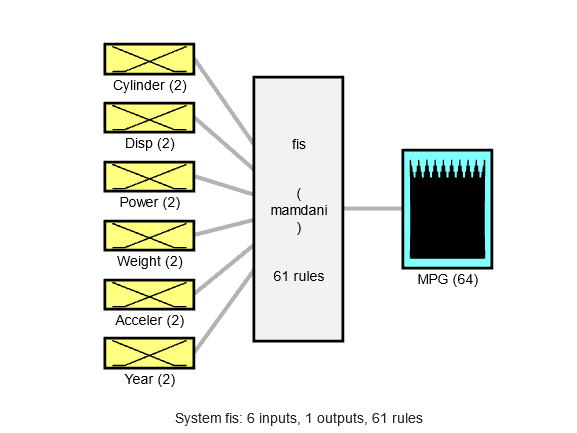

% Mostramos el nuevo FIS
plotfis(fisout1)

Ahora podemos ver cuáles son los resultados que predice nuestro FIS sólo con las nuevas reglas añadidas. Para esto utilizaremos la función `plotActualAndExpectedResultsWithRMSE`.

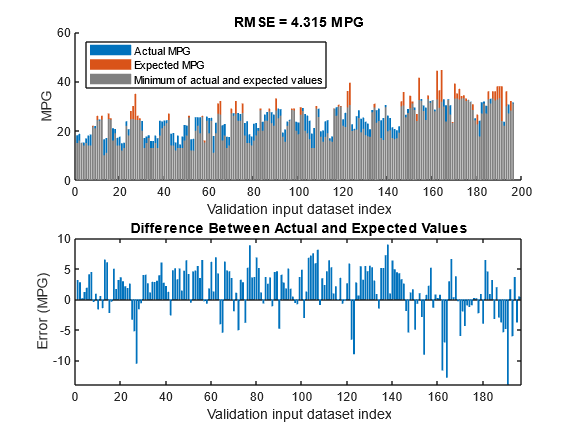

plotActualAndExpectedResultsWithRMSE(fisout1,vldX,vldY);

### Optimización de todos los parámetros

[in, out, rule] = getTunableSettings(fisout1);
options.OptimizationType = 'tuning';
options.Method = 'patternsearch';
options.MethodOptions.MaxIterations = 60;
% Para mejorar los resultados
options.MethodOptions.UseCompletePoll = true;

% Optimizamos los parámetros
rng('default')
fisout = tunefis(fisout1, [in; out; rule], trnX, trnY, options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1        4.45215             1      
    1        1013        4.25259             2     Successful Poll
    2        1775        3.99335             4     Successful Poll
    3        2250        3.73151             8     Successful Poll
    4        2670        3.53114            16     Successful Poll
    5        2994        3.43059            32     Successful Poll
    6        3136        3.34226            64     Successful Poll
    7        3164        3.30848           128     Successful Poll
    8        3183        3.28205           256     Successful Poll
    9        3199        3.23967           512     Successful Poll
   10        3209        3.21039          1024     Successful Poll
   11        3215        3.16173          2048     Successful Poll
   12        3220        3.16173          1024     Refine Mesh
   13        3227        3.16173           512     Refine Mesh
   14        3238        3

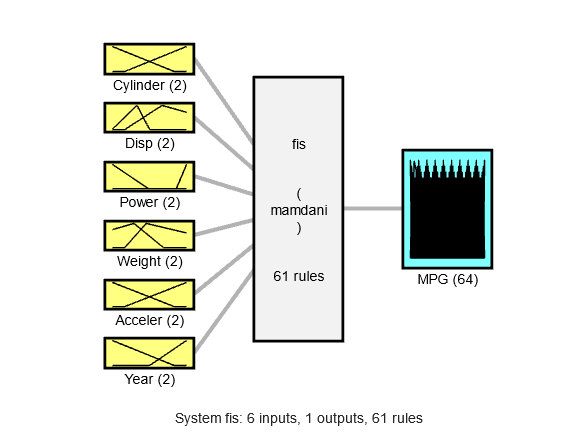

% Mostramos el FIS obtenido
figure;
plotfis(fisout);

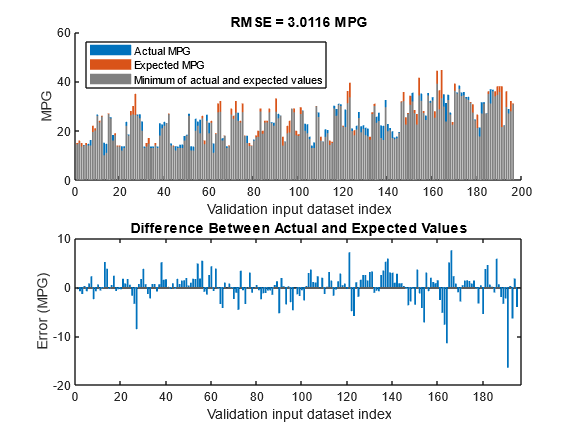


% Probamos el desempeño de nuestro FIS
plotActualAndExpectedResultsWithRMSE(fisout,vldX,vldY)

Como se puede observar, disminuyó el error al optimizar también las funciones de membresía.

## Funciones

#### Función de costo

function cost = customcostfcn(fis, x, y)
    % Evaluamos el FIS para obtener los valores de sin(x), cos(x) y exp(x)
    tY = evalfis(fis,x);
    sincosx = tY(:,1)+tY(:,2);     % sin(x) + cos(x)
    sincosexpx = sincosx.*tY(:,3); % (sin(x) + cos(x)) / exp(x)
    actY = [sincosx;sincosexpx];
    d = y(:)-actY;  % Resta de la Y de entrenamiento menos Y con los datos del FIS
    cost = sqrt(mean(d.*d)); % RMSE
end

#### Función personalizada de optimización

function fis = customtunefis(fis,rule,x,y,n,ignore)
    % Show the initial cost.
    cost = findcost(fis,x,y);
    fprintf( 'Initial cost = %f\n' ,cost);
    % Optimize the rule parameters.
    numMFs = numel(fis.Outputs.MembershipFunctions);
    for ite = 1:n
        for i = 1:numel(rule)
            % Get the consequent value.
            pval = getTunableValues(fis,rule(i));
            % Loop through the output MF indices to minimize the cost.
            % Use the output indices according to AllowNot and AllowEmpty.
            allowNot = rule(i).Consequent.AllowNot;
            allowEmpty = rule(i).Consequent.AllowEmpty;
            if allowNot && allowEmpty
                mfID = -numMFs:numMFs;
            elseif allowNot && ~allowEmpty
                mfID = [-numMFs:-1 1:numMFs];
            elseif ~allowNot && allowEmpty
                mfID = 0:numMFs;
            else
                mfID = 1:numMFs;
            end
            cost = 1000;
            minCostFIS = fis;
            for j = 1:length(mfID)
                % Update the consequent value.
                pval(1) = mfID(j);
                % Set the consequent value in the FIS.
                fis = setTunableValues(fis,rule(i),pval, 'IgnoreInvalidParameters' ,ignore);
                % Evaluate cost.
                rmse = findcost(fis,x,y);
                % Update the FIS with the minimum cost.
                if rmse < cost
                    cost = rmse;
                    minCostFIS = fis;
                end
            end
            fis = minCostFIS;
        end
        fprintf( 'Iteration %d: Cost = %f\n' ,ite,cost);
    end
end

% Funcion de costo para el segundo ejemplo
function cost = findcost(fis,x,y)
    actY = evalfis(fis,x);
    d = y - actY;
    cost = sqrt(mean(d.*d));
end

#### Función para graficar las predicciones de nuestro FIS

function plotActualAndExpectedResultsWithRMSE(fis, x, y)
    % Obtenemos el error medio cuadratico RMSE
    [rmse, actY] = calculateRMSE(fis, x, y);

    % Graficamos los resultados
    figure;
    subplot(2,1,1);
    hold on;
    bar(actY);
    bar(y);
    bar(min(actY,y), 'FaceColor' ,[0.5 0.5 0.5]);
    hold off;
    axis([0 200 0 60])
    xlabel( "Validation input dataset index" ),ylabel( "MPG" )
    legend([ "Actual MPG" "Expected MPG" "Minimum of actual and expected values" ], ...
     'Location' , 'NorthWest' )
    title( "RMSE = "  + num2str(rmse) + " MPG" )

    subplot(2,1,2)
    bar(actY-y)
    xlabel( "Validation input dataset index" ),ylabel( "Error (MPG)" )
    title( "Difference Between Actual and Expected Values" )
end

% Function para obtener el RMSE
function [rmse,actY] = calculateRMSE(fis, x, y)
    % Opciones para evaluar el FIS
    persistent evalOptions
    if isempty(evalOptions)
     evalOptions = evalfisOptions( "EmptyOutputFuzzySetMessage" , "none" , ...
            "NoRuleFiredMessage" , "none" , "OutOfRangeInputValueMessage" , "none" );
    end

    % Evaluamos el FIS
    actY = evalfis(fis, x, evalOptions);
    % Calculamos el RMSE
    del = actY - y;
    rmse = sqrt(mean(del.^2));
end